# **Dispositivo de Tiro con Arco**

**Métodos Numéricos Aplicados 1**

***Autor****: Javier Blanco*

*UNIR, 2023- 2024*

## Planteamiento

Se cuenta con un sistema de tiro con arco (**ver figura**) desde donde se han recopilado datos de la fuerza **F** en newtons necesaria para estirar la cuerda una distancia **x** en metros. 

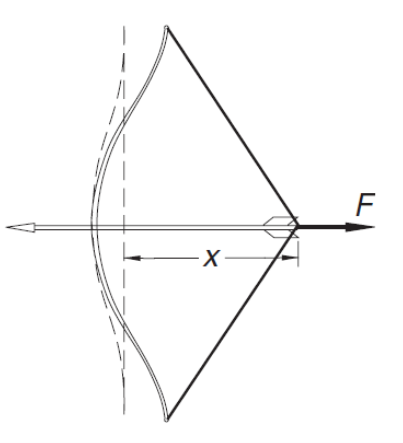

Se requiere determinar la velocidad (m/s) a la que flecha es disparada del arco en función del trabajo realizado (energia empleada) en el momento del tiro cuando el deplazamiento x = 0.5 m. 

## Datos

Los datos de la fuerza F en función del desplazamiento x se muestran en la siguiente tabla:

archery_data = readtable("arch_data.dat")

archery_data = 11×2 table
    x_m_    F_N_
    ____    ____

       0      0 
    0.05     37 
     0.1     71 
    0.15    104 
     0.2    134 
    0.25    161 
     0.3    185 
    0.35    207 
     0.4    225 
    0.45    239 
     0.5    250 


De la tabla anterior podemos deducir los limites de integración [a,b], a = 0, b = 0.5 en el dominio. Además, sabemos que la flecha cuenta con una masa m = 0.075 Kg. Como dato extra, podemos asumir que el trabajo realizado **W** es igual a la energía cinética **Ec** de la flecha al instante de ser disparada, por lo cual podemos hacer la siguiente estimación:


$$\begin{array}{l}
W=E_c \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)\\
E_c =\frac{1}{2}m*V^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)\\
W=\int_a^b F\;\mathrm{dx}=F\;\int_a^b \mathrm{dx}\;\;\left(3\right)
\end{array}$$


Igualanddo (2) y (3) se obtiene:


$$F\;\int_a^b \mathrm{dx}=\frac{1}{2}m*V^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\right)\;$$


Llamaremos el lado izquiero de la igualdad $I$, quedando la expresión anterior de la siguiente forma:


$$I=\frac{1}{2}m*V^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\right)$$


Si despejamos la V, se tiene:


$$V=\sqrt{\frac{2*I}{m}\;}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(6\right)$$


Donde:

$I:$ Valor de la integral obtenida numéricamente, (area bajo la curva)

$m:$ masa del proyectil, en este caso la flecha en Kg

$V:$ Velocidad del proyectil en m/s

## Solución Técnica

### Análisis y Consideraciones

Para calcular la velocidad que alcanzaría el proyectil a una distancia x = 0.5 utilizaremos métodos numéricos de aproximación, más concretamente la integración numérica que se enmarca dentro de las técnicas de *Newton-Cotes*, ya que evaluaremos la integral $I\;$ definida en los intervalos [a, b] equiespaciados.  Los métodos de integración numérica requeridos son el método del **Trapecio** y **Simpson 1/3**. Sin embargo, también se han incluido los métodos de **Simpson 3/8** y **Punto medio**, ambos muy aceptados por su rápida convergencia y buena precisión respectivamente. 

Se desarrollaron las funciones **trapezium.m**,** simpson13.m**, **simpson38.m** y **midpoint.m **(*Ver ANEXOS*), las cuales están preparadas para recibir o bien una función de integración con solución analítica conocida, o bien datos de entrada en forma de tabla, como es el caso de esta actividad. Cada función matlab desarrollada requerirá como entrada un vector $f\left(x\right)=\left\lbrack f\left(x_1 \right),f\left(x_2 \right),f\left(x_3 \right),\ldotp \ldotp \ldotp f\left(x_n \right)\right\rbrack$, los intervalos [a, b] y el número de subintervalos $n$ que dependerá del método que estemos usando, por ejemplo, para *Simpson 1/3 *se requiere que *n* sea par, y para *Simpson 3/8*, *n* sea múltiplo de 3. Las funciones antesmencionadas son de tipo compuesta.

### Funciones de Error

Cuando la función de integración es desconocida el cálculo del error requiere de ecuaciones que involucran al tamaño de paso h y una derivada de orden superior sobre los datos que se están tratando. Cada método tiene su propia ecuación particular para el error:


$$$err_{Trapezium} = - \frac{h^2}{12} \cdot (b-a) \cdot f''(\xi)$$$



$$$err_{Simpson13} = - \frac{h^4}{180} \cdot (b-a) \cdot f^{iv}(\xi)$$$



$$$err_{simpson38} = \frac{n \cdot h^5}{80} \cdot f^{iv}(\xi)$$$



$$$err_{midpoint} = \frac{(b-a)^3}{24 \cdot n^2} \cdot f''(\xi)$$$


### Evaluación de lntegral

La aplicación de las técnicas numéricas de integración se muestra en el siguiente código:

x = archery_data.x_m_;
F = archery_data.F_N_;
a = x(1); % lower bound 
b = x(end); % upper bound
n = length(x); % number of intervals
F = F'; % function of x (f(x))
m = 0.075; % mass in kg of arrow
% CALLING NUMERIC METHODS:
% Trapezium
% Simpson 1/3
% Simpson 3/8
% MidPoint
[I_trapezium, err_trapezium] = trapezium(0, F, a, b, n);
[I_simpson, err_simpson] = simpson13(0, F, a, b, 10); %n even
[I_simpson38, err_simpson38] = simpson38(0, F, a, b, 9); %n multiple of 3
[I_mp, err_mp] = midpoint(0, F, a, b, n);
Ints = [I_trapezium, I_simpson, I_simpson38, I_mp];
Errs = [err_trapezium, err_simpson, err_simpson38, err_mp];

part_1_table = table(Ints', Errs','RowNames', ...
    {'Trapezium', 'Simpson 1/3', 'Simpson 3/8', 'MidPoint'}, ...
    'VariableNames',{'Integral', 'Error'});
disp(part_1_table);

                       Integral                Error        
                   ________________    _____________________

    Trapezium      67.6363636363636     8.60881542699725e-05
    Simpson 1/3    74.5333333333333    -3.47222222222222e-08
    Simpson 3/8    79.3958333333333     1.19074836153025e-07
    MidPoint       73.3181818181818    -4.30440771349862e-05



El método de Simpson 1/3 exhibe una mayor precisión en comparación con el método del trapecio y el método de Simpson 3/8. Además, el método del punto medio demuestra un error inferior en comparación con el método del trapecio. La jerarquía de precisión entre los métodos evaluados para esta actividad se puede establecer de la siguiente manera: 

*Simpson 1/3 > Simpson 3/8 > Punto Medio > Trapecio*

### Cálculo de la Velocidad

La velocidad de la flecha en todos puntos dados viene tras la evaluación de la integral de [a,b], tal como se muestra a continuación:

% Evaluation Integration according method's requirements individually
In = zeros([length(x) 1]);
for i=2:length(x)
    y_temp = F(1:i);
    b = x(i);
    if mod(i, 2) ~= 0 
        In(i) = simpson13(0, y_temp, a, b, i-1);
    else
        In(i) = trapezium(0, y_temp, a, b, i);
    end
end
% Velocoity at x = 0.5 m with m = 0.075 kg
V_numeric = sqrt((2 .* In) / m);
part_2_table = table(x, F', In, V_numeric, 'VariableNames', ...
    {'x (m)', 'F (N)' ,'I', 'V calc. m/s'});
disp(part_2_table)

    x (m)    F (N)           I              V calc. m/s   
    _____    _____    ________________    ________________

       0        0                    0                   0
    0.05       37               0.4625    3.51188458428425
     0.1       71                 3.65    9.86576572463249
    0.15      104                    6    12.6491106406735
     0.2      134                   14    19.3218356615859
    0.25      161     17.7708333333333    21.7689891563409
     0.3      185                30.05    28.3078316607495
    0.35      207            34.803125    30.4644601680931
     0.4      225     50.6833333333333    36.7635084772326
    0.45      239              55.9575    38.6290046467677
     0.5      250     74.5333333333333    44.5820093261346



Podemos determinar V cuando x=0.5:

% V @ 0.5 m
V_05 = interp1(part_2_table.("x (m)"), part_2_table.("V calc. m/s"), 0.5, 'linear');
disp(['Cuando x = ', num2str(0.5),' kg', ', V = ', num2str(V_05), ' m/s']);

Cuando x = 0.5 kg, V = 44.582 m/s


Dado que hemos aproximado la evaluación de la integral, podemos graficar el area bajo la curva (AUC):

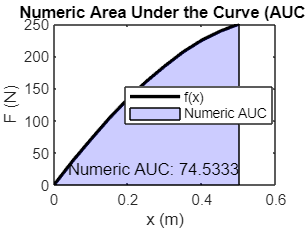

figure;
plot(x, F, 'k-', 'LineWidth', 2);
hold on;
x_fill = [a, x(2:end)', b];
y_fill = [0, F(2:end), 0];
fill(x_fill, y_fill, 'b', 'FaceAlpha', 0.2);%area under the curve
xlabel('x (m)');
ylabel('F (N)');
title('Numeric Area Under the Curve (AUC)');
legend('f(x)', 'Numeric AUC', Location='best');
text(b, 25, ['Numeric AUC: ', num2str(In(end))], 'HorizontalAlignment', 'right');

### Misceláneos

Adicionalmente, sería interesante aproximar la curva obtenida a una función analitica, más concretamente a un polinomio. De esta manera podemos resolver la integral y comparar con el resultado numérico. El polinomio de aproximación se obtiene por método de Lagrange (**visto en el tema 4 de la asignatura**). 

%% BONUS PART %%
t = linspace(a, b, 100);
[p, err_lagrange, coeffs] = lagrange_interpolation(x, F, 2, t);
syms z; 
p_sym = poly2sym(coeffs, z);% symbolic polynomial
integral_sym = int(p_sym, z); % Symbolic polynomial integration
symb_auc = double(subs(integral_sym, z, b) - subs(integral_sym, z, a)); % Barrow's Rule
fprintf('Analytical AUC between %.2f y %.2f: %.4f\n', a, b, symb_auc);

Analytical AUC between 0.00 y 0.50: 74.5196


Gráficamente se puede observar de la siguiente forma:

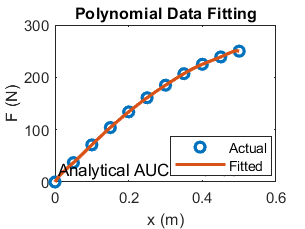

figure;
plot(x, F, 'o', t, p, '-', 'LineWidth', 2);
legend('Actual', 'Fitted', Location='best');
xlabel('x (m)');
ylabel('F (N)');
title('Polynomial Data Fitting');
text(b, 25, ['Analytical AUC: ', num2str(symb_auc)], ...
    'HorizontalAlignment', 'right');

El polinomio de Lagrange de grado 2 aproxima significativamente la función de F vs x del sistema de tiro con arco. El error relativo porcentual entre el método analítico y la aproximación numérica obtenida por Simpson 1/3:

err_rel = (abs(symb_auc - In(end)) / symb_auc) * 100;
fprintf('Relative Error AUC: %.4f\n', err_rel);

Relative Error AUC: 0.0184


## Conclusiones

- Se logró determinar la velocidad de la flecha en el momento del disparo mediante métodos numéricos.

- Los métodos utilizados fueron el método del Trapecio, Simpson 1/3, Simpson 3/8 y Punto Medio.

- Se desarrollaron funciones MATLAB para cada método y se evaluaron numéricamente.

- Simpson 1/3 demostró ser el método más preciso para la integración numérica en este contexto.

- Se determinó la velocidad V de la flecha (44.582 m/s) para x=0.5 m utilizando la integral numérica.

- El análisis adicional incluyó la aproximación de la curva de fuerza con un polinomio de Lagrange y la comparación de AUC numérico y analítico, mostrando un error relativo porcentual de 0.0184%.

## Referencias

- Regla de Simpson. Disponible en: [https://es.wikipedia.org/wiki/Regla_de_Simpson](https://es.wikipedia.org/wiki/Regla_de_Simpson) 

- Carrillo, J. (2021). La regla de Simpson: la fórmula y cómo funciona. Disponible en: [https://www.freecodecamp.org/espanol/news/la-regla-de-simpson-la-formula-y-como-funciona/](https://www.freecodecamp.org/espanol/news/la-regla-de-simpson-la-formula-y-como-funciona/) 

- Tema 5, Unidad Didáctica Integración Numerica. Metodos Numéricos Aplicados 1. UNIR.

- OpenStax (s.f). Integración Numérica. Disponible en: [https://openstax.org/books/c%C3%A1lculo-volumen-2/pages/3-6-integracion-numerica](https://openstax.org/books/c%C3%A1lculo-volumen-2/pages/3-6-integracion-numerica)

## Anexos

### Funciones y Módulos

- **Método Simpson 1/3:**

- **Método Simpson 3/8**

- **Método del Trapecio**

- **Método del Punto Medio**

### Gráficos Adicionales